I instantiated d1 in another script. Here's the plot, directed adjacency matrix and coordinates:

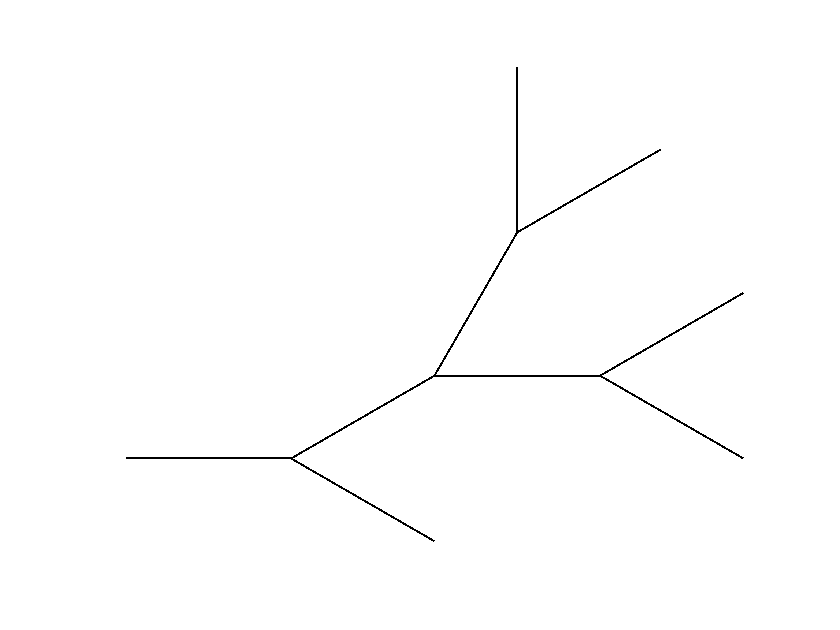

Current plot held


ans =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


d1.plot

d1.dA

ans =      0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     1     0     0     0     0     0     0     0     0


[d1.X d1.Y]

ans =          0         0
   10.0000         0
   18.6603    5.0000
   23.6603   13.6603
   23.6603   23.6603
   32.3205   18.6603
   28.6603    5.0000
   37.3205   10.0000
   37.3205         0
   18.6603   -5.0000


I have already worked out what the strahler vector should be, by hand.

idealStrahler = [3 3 3 2 1 1 2 1 1 1]

idealStrahler =      3     3     3     2     1     1     2     1     1     1


First get the BCT for the dendrite that we're working with. Create a strahler vector with the same number of elements. Start this vector with all zeros, because a strahler number cannot be zero. So if any zeros remain at the end, it means there was an error. It could also be a node that is not attached to anything.

d1.BCT

ans =      1     2     2     2     0     0     2     0     0     0


strahler = zeros(1,d1.nodes);

Set all of the strahler values of the termination (BCT==0) nodes to 1.

strahler(d1.BCT==0) = 1

strahler =      0     0     0     0     1     1     0     1     1     1


Now I want to scroll through all of the other nodes until they are all filled. In a properly constructed dendrite, the nodes near the termination points will be closer to the end. So I'll scroll backwards through the nodes.

while(sum(strahler==0)>0)
    for i = d1.nodes:-1:1
        if(strahler(i)==0)
            branchStrahlers = strahler(find(d1.dA(:,i)));
            
            % First check if there's only one element of the branchStrahlers vector
            % If so, just make the ith strahler equal to the branchStrahler value.
            if(length(branchStrahlers)==1)
                strahler(i) = branchStrahlers(1);
            %Check if each of the branches has the same strahler number.
                % If so then the ith strahler number is one greater.
                % Unless it's zero, in which case, just keep it zero for now.
            elseif( branchStrahlers(1) == branchStrahlers(2))
                    strahler(i) = branchStrahlers(1);
                    if(strahler(i)>0)
                        strahler(i) = strahler(i)+1;
                    end
                    
            else
                % IF the strahlers of the branch don't match, but aren't zero, then set the ith strahler to the 
                % max strahler of the branches.
                if(sum(branchStrahlers==0)>0)
                    strahler(i) = 0;
                else
                    strahler(i) = max(branchStrahlers);
                end
            end
        end
    end
end

strahler

strahler =      3     3     3     2     1     1     2     1     1     1


strahler - idealStrahler

ans =      0     0     0     0     0     0     0     0     0     0
